DGA([2 0 0],[2 1])

FINAL = 12×12 string array
    "e0"       "e1"        "e2"       "e12"      "D1"       "D2"       "e1D1"      "e2D1"     "e12D1"    "e1D2"      "e2D2"     "e12D2"
    "e1"       "e0"        "e12"      "e2"       "e1D1"     "e1D2"     "D1"        "e12D1"    "e2D1"     "D2"        "e12D2"    "e2D2" 
    "e2"       "-e12"      "e0"       "-e1"      "e2D1"     "e2D2"     "-e12D1"    "D1"       "-e1D1"    "-e12D2"    "D2"       "-e1D2"
    "e12"      "-e2"       "e1"       "-e0"      "e12D1"    "e12D2"    "-e2D1"     "e1D1"     "-D1"      "-e2D2"     "e1D2"     "-D2"  
    "D1"       "e1D1"      "e2D1"     "e12D1"    "0"        "0"        "0"         "0"        "0"        "0"         "0"        "0"    
    "D2"       "e1D2"      "e2D2"     "e12D2"    "0"        "0"        "0"         "0"        "0"        "0"         "0"        "0"    
    "e1D1"     "D1"        "e12D1"    "e2D1"     "0"        "0"        "0"         "0"        "0"        "0"         "0"        "0"    
    "e2D1"     "-e12D

Parámetros polares en R2

syms phi r x y real
PHI=phi+D1;
R=r+D2;


Una función muy simple, la rotación de un punto

p=R*e1; % Un punto con coordenada x=r
P=simplify(exp(-1/2*PHI*e12)*p*exp(1/2*PHI*e12)) % La rotación del punto

P = ( r*cos(phi) )*e1+( r*sin(phi) )*e2+( -r*sin(phi) )*e1D1+( r*cos(phi) )*e2D1+( cos(phi) )*e1D2+( sin(phi) )*e2D2

P.tangent(0) % La función original

ans = ( r*cos(phi) )*e1+( r*sin(phi) )*e2

Este resultado es la relación bàsica entre las coordenadas 


$$x=r\cos(\phi)\\
y=r\sin(\phi)$$


diferenciando obtenemos


$$dx=dr\cos(\phi)-r\sin(\phi)d\phi\\
dy=dr\sin(\phi)+r\cos(\phi)d\phi$$


dphi=P.shift("D1") % D1 es la dirección de d\phi

dphi = ( -r*sin(phi) )*e1+( r*cos(phi) )*e2

dr=P.shift("D2") % D2 es la dirección de dr

dr = ( cos(phi) )*e1+( sin(phi) )*e2

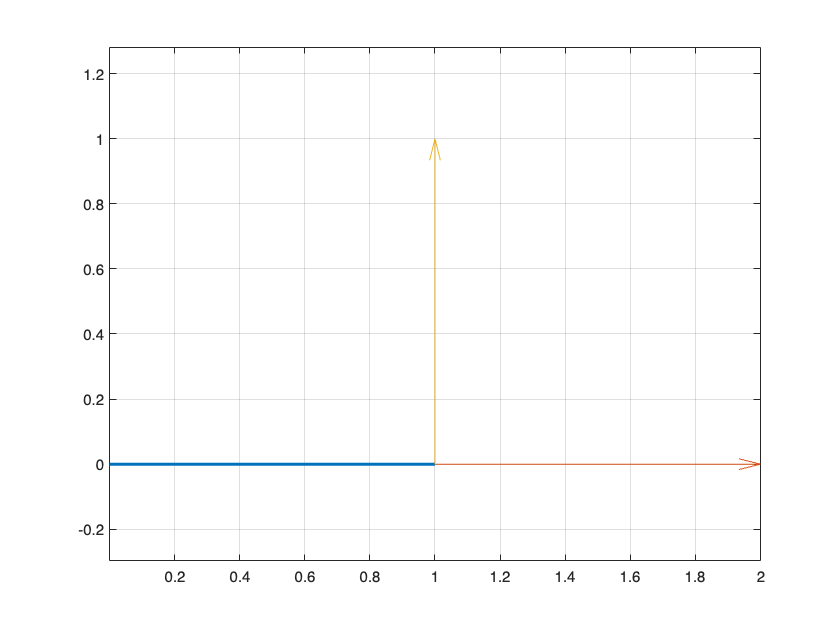

drawArrow = @(x,y) quiver( x(1),y(1),x(2)-x(1),y(2)-y(1),0 );
r=1;phi=0;
p=eval(char(P));
p_actual=p.tangent(0);
figure()
plot([0,p_actual(e1)],[0,p_actual(e2)],'LineWidth',2);
hold on;grid on;
dr=p.shift("D2");
drawArrow([p_actual(e1),p_actual(e1)+dr(e1)],[p_actual(e2),p_actual(e2)+dr(e2)]);
dphi=p.shift("D1");
drawArrow([p_actual(e1),p_actual(e1)+dphi(e1)],[p_actual(e2),p_actual(e2)+dphi(e2)]);
axis equal

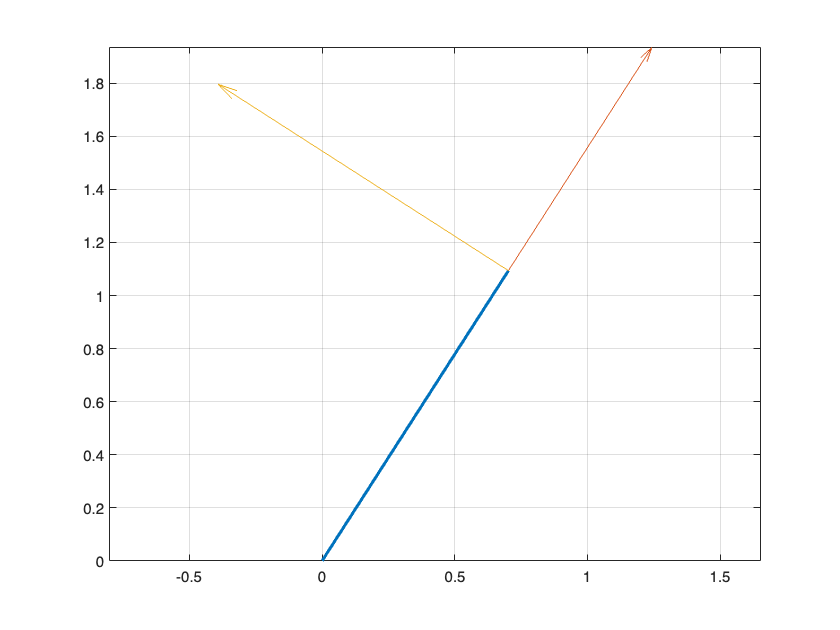

r=1.3;phi=1;
p=eval(char(P));
p_actual=p.tangent(0);
figure()
plot([0,p_actual(e1)],[0,p_actual(e2)],'LineWidth',2);
hold on;grid on;
dr=p.shift("D2");
drawArrow([p_actual(e1),p_actual(e1)+dr(e1)],[p_actual(e2),p_actual(e2)+dr(e2)]);
dphi=p.shift("D1");
drawArrow([p_actual(e1),p_actual(e1)+dphi(e1)],[p_actual(e2),p_actual(e2)+dphi(e2)]);
axis equal

syms phi r x y real
PHI=phi+D1;
R=r+D2;
p=R*e1; % Un punto con coordenada x=r
destino=x*e1+y*e2;
Err=P-destino % El error respecto al destino

Err = ( r*cos(phi) - x )*e1+( r*sin(phi) - y )*e2+( -r*sin(phi) )*e1D1+( r*cos(phi) )*e2D1+( cos(phi) )*e1D2+( sin(phi) )*e2D2

Vamos a proyectar el error sobre las coordenadas de los parámetros para saber cuanto nos tenemos que mover

err=Err.tangent(0);
dphi=Err.shift("D1");
dr=Err.shift("D2");
err_dphi=simplify((err.*dphi)); %Proyección del error sobre dphi, hay que dividir por modulo(dphi)^2
err_dr=simplify((err.*dr));     %proyección del error sobre dr, hay que dividir por modulo(dr)^2
abs_err=(err*err');
phi_new=matlabFunction((phi-err_dphi(e0)*0.15))

phi_new = function_handle with value:
    @(phi,r,x,y)phi+r.*(y.*cos(phi)-x.*sin(phi)).*(3.0./2.0e+1)


r_new=matlabFunction(r-err_dr(e0)*0.18)

r_new = function_handle with value:
    @(phi,r,x,y)r.*(4.1e+1./5.0e+1)+x.*cos(phi).*(9.0./5.0e+1)+y.*sin(phi).*(9.0./5.0e+1)


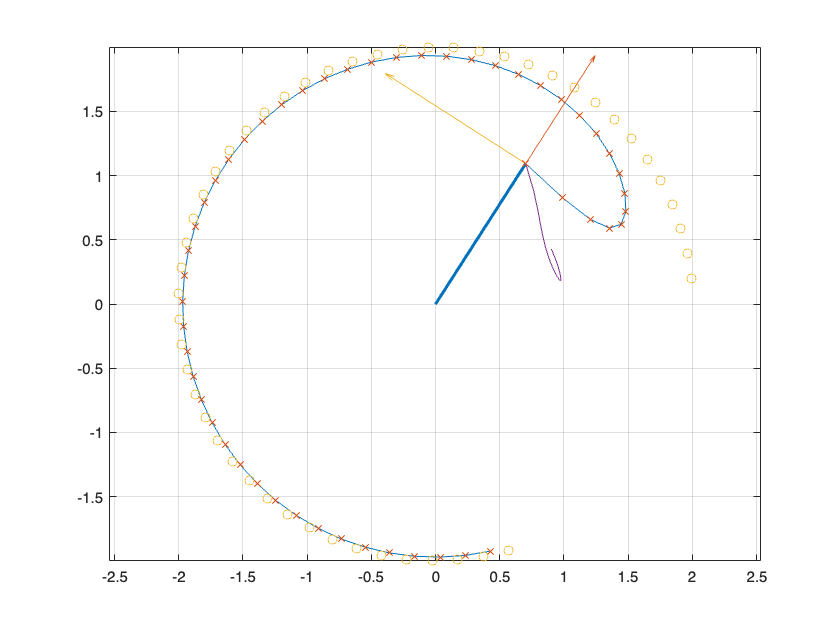

r=1.3;phi=1; %parametros iniciales
x=-2;y=3;   %destino

p=eval(char(P));
tx=[p(e1)];ty=[p(e2)];
X=2*real(exp(0.1*(1:50)*1i));
Y=2*imag(exp(0.1*(1:50)*1i));
for i=1:50
    x=X(i);
    y=Y(i);
    r=r_new(phi,r,x,y);
    phi=phi_new(phi,r,x,y);
    p=eval(char(P));
    tx=[tx p(e1)];
    ty=[ty p(e2)];
end
plot(tx,ty);
hold on;
plot(tx,ty,'x')
plot(X,Y,'o'p)